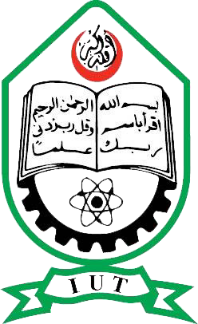

Islamic University of Technology

Name                          : Shazzad Ahmed 

Student ID                   : 220021108 

Section                        : A-(02) 

Department                 :EEE 

Course No                    : EEE-4408

Course Title                 : **Random Signals &        Processes Lab**

Experiment No            : 4 

Experiment Name      : Homework

Date of Submission    : 16/08/2025

**Problem 1:**

A **one-tailed test** evaluates whether a parameter differs from a hypothesized value in a **specific direction**. It is applied when the concern is only whether the value is either greater than or less than the benchmark, but not both. The rejection region lies entirely in one tail of the distribution.

A **two-tailed test** evaluates whether a parameter differs from a hypothesized value in **either direction**. It is used when both higher and lower deviations are important. In this case, the rejection region is split equally between both tails of the distribution.

**Example – One-Tailed Test:**

If a soft drink company claims that each bottle contains at least 500 mL, the hypothesis test may focus only on whether the average volume is **less than 500 mL**. This situation requires a one-tailed test because only a shortage is of interest.

**Example – Two-Tailed Test:**

If there is suspicion that the filling process is inaccurate in either direction—bottles may contain **less than or more than 500 mL**—then a two-tailed test is appropriate, as both possibilities must be considered.

**Example – Heights:**

If the assumed average height of a group of students is 160 cm:

- In a one-tailed test, the alternative hypothesis would specify that the average is **greater than 160 cm** or **less than 160 cm**, depending on the direction of interest.

- In a two-tailed test, the alternative hypothesis would specify that the average is **not equal to 160 cm**, meaning it could be either higher or lower.

Question-2 

Problem-1:

MU=503;
sigma=1.4;
x=505;
z=(x-MU)/sigma;
probability=1-(normcdf(z,0,1))

probability = 0.0766

Problem-2:

a=[495 510 505 496 504 509 509 503];
b=[503 504 501 504 506 498 497 499];
MU_A=mean(a);
MU_B=mean(b);
SD_A=sqrt(sum((MU_A-a).^2)/(numel(a)-1));
SD_B=sqrt(sum((MU_B-b).^2)/(numel(b)-1));
t=(MU_A-MU_B)/(sqrt(((SD_A^2)/numel(a))+((SD_B^2)/numel(b))));
dof=((((SD_A^2)/numel(a))+((SD_B^2)/numel(b)))^2)/(((((SD_A^2)/numel(a))^2)/(numel(a)-1))+((((SD_B^2)/numel(b))^2)/(numel(b)-1)));
p1 = 2*(1-tcdf((abs(t)),dof))

p1 = 0.3320

if p1<0.05
disp('reject null hypothesis or in other words there is a significant difference between the two sets')
else
disp('null hypothesis stays or in other words there is no significant difference between the two sets' )
end

null hypothesis stays or in other words there is no significant difference between the two sets


[h,p,CI,STATS] = ttest2(a,b,0.05)

h = 0

p = 0.3275

CI =    -2.6458    7.3958


STATS = struct with fields:
    tstat: 1.0146
       df: 14
       sd: 4.6818


Problem-3:

The **null hypothesis** states that the mean hardness of all ductile iron pieces is **170** (μ = 170).

The **alternative hypothesis** states that the mean hardness of all ductile iron pieces is **greater than 170** (μ > 170).

This represents a **one-tailed test**, since the interest lies only in determining whether the mean exceeds the specified value.

hardness=[170 167 174 179 179 187 179 183 179
    156 163 156 187 156 167 156 174 170
    183 179 174 179 170 159 187 170 168
    170 167 174 179 156 167 156 159 187];
% Hypotheses: % H0:mu=170 % H1:mu>170 
[~, p_val2, ci2, stats2] = ttest(hardness, 170, ...
    'Tail', 'right') %right sided t-test

p_val2 =     0.5167    0.6042    0.5407    0.0059    0.7690    0.5000    0.5231    0.3914    0.1320


ci2 =   156.7753  160.8477  158.9099  176.2933  151.9591  155.9453  150.7591  159.7922  165.6970
       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf


stats2 = struct with fields:
    tstat: [-0.0453 -0.2887 -0.1111 5.5000 -0.8411 0 -0.0628 0.3015 1.3705]
       df: [3 3 3 3 3 3 3 3 3]
       sd: [11.0265 6.9282 9 4 11.2953 11.9443 15.9269 9.9499 8.7560]


if p_val2 < 0.05
disp('Reject H0: Mean hardness > 170.');
else
disp('Fail to reject H0: Not enough evidence mean hardness > 170.')
end

Fail to reject H0: Not enough evidence mean hardness > 170.
